### **Adjustable Arrowheads**

In this visualization, I used MATLAB's `quiver` function to create arrows with adjustable arrowhead sizes, enhancing their clarity and appearance. Customizing arrowheads is particularly useful for emphasizing direction and magnitude, especially when arrows vary in length.

I began by defining the start and end points for two arrows. For each arrow, I calculated the vector components by subtracting the starting coordinates from the ending ones. Using the `quiver` function, I plotted the arrows and adjusted the `MaxHeadSize` property to 1.5, which enlarged the arrowheads. This customization made the arrowheads more prominent, ensuring they remained visible even in larger plots.

To differentiate between the two arrows, I used blue for the first arrow and red for the second. I also set the axis limits and enabled the grid to improve readability and provide context for the arrow positions.

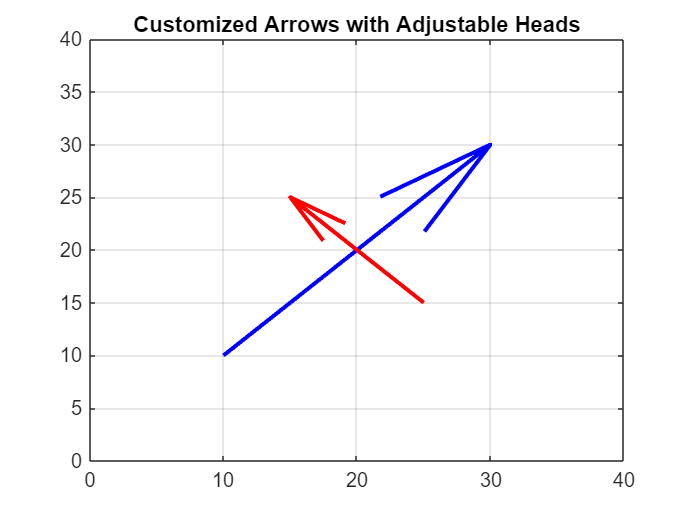

% Drawing Arrows with Adjustable Arrowheads
% I want to customize the size and appearance of the arrowheads.

% Define the start and end points for two arrows
x1 = [10, 30]; y1 = [10, 30]; % Arrow 1
x2 = [25, 15]; y2 = [15, 25]; % Arrow 2

% Plot the arrows with customized heads
figure;
quiver(x1(1), y1(1), x1(2) - x1(1), y1(2) - y1(1), 0, 'b', 'LineWidth', 2, 'MaxHeadSize', 1.5); % First arrow
hold on;
quiver(x2(1), y2(1), x2(2) - x2(1), y2(2) - y2(1), 0, 'r', 'LineWidth', 2, 'MaxHeadSize', 1.5); % Second arrow
xlim([0, 40]);
ylim([0, 40]);
grid on;
title('Customized Arrows with Adjustable Heads');